  
X = [-2.5 0 2.5]

X =    -2.5000         0    2.5000


Y = [0 1.67 0]

Y =          0    1.6700         0


n  = length(X)

n = 3

A = sym('A', [1 n]);
B = sym('B', [1 n-1]);
C = sym('C', [1 n-1]);
H = sym('H', [1 n-1]);
for i = 1:n-1
    H(i) = X(i+1) - X(i);
end
for k = 1:n-2
    eqns(k) = H(k)*A(k) + 2*(H(k)+H(k+1))*A(k+1) + H(k+1)*A(k+2) == (Y(k+2)-Y(k+1))/H(k+1)-(Y(k+1)-Y(k))/H(k);
end
H

$$H = \left(\begin{array}{cc} \frac{5}{2} & \frac{5}{2} \end{array}\right)$$

%for natural spline
eqns(n-1) = A(1)==0;
eqns(n) = A(n)==0 ; 
eqns

$$eqns = \left(\begin{array}{ccc} \frac{5\,A_{1}}{2}+10\,A_{2}+\frac{5\,A_{3}}{2}=-\frac{167}{125} & A_{1}=0 & A_{3}=0 \end{array}\right)$$


S = solve(eqns)

S = struct with fields:
    A1: 0
    A2: -167/1250
    A3: 0



A(1) = S.A1;
A(2) = S.A2; A(3) = S.A3       

$$A = \left(\begin{array}{ccc} 0 & -\frac{167}{1250} & 0 \end{array}\right)$$

A = double(A)

A =          0   -0.1336         0



for k = 1:n-1
    B(k) = Y(k)/H(k) - A(k)*H(k);
    C(k) = Y(k+1)/H(k) - A(k+1)*H(k);
end
B = double(B)

B =          0    1.0020


C = double(C)

C =     1.0020         0


H = double(H)

H =     2.5000    2.5000


x  = 0:0.01:X(n)

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


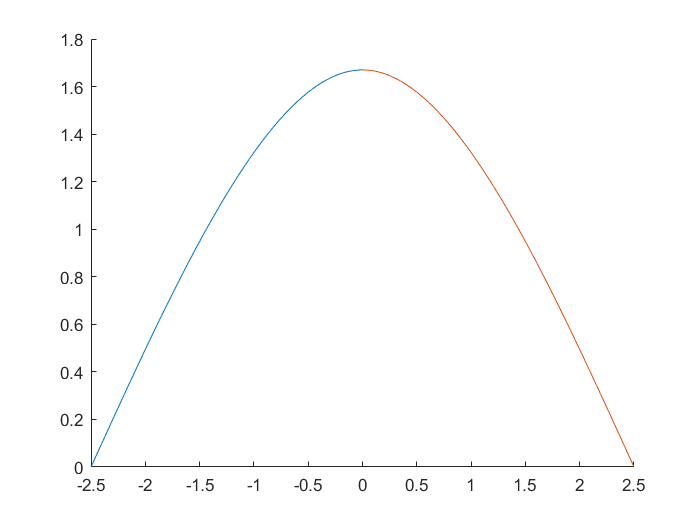

hold on
for k = 1:n-1
    x = X(k):0.001:X(k+1);
    S = A(k)*(X(k+1)-x).^3/H(k) + A(k+1)*(x-X(k)).^3/H(k) + B(k)*(X(k+1)- x) + C(k)*(x - X(k));
    plot(x,S)
end
hold off




% for i = 1:n
%     str1 = 'A';
%     str2 = num2str(i);
%     fieldname = append(str1,str2)
%     A(i) = solve(eqns, fieldname)
% end






